# Plots

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Qband spectrum with lines at g = 2.003 and g = 2.0065

gm_07_20230622_fit

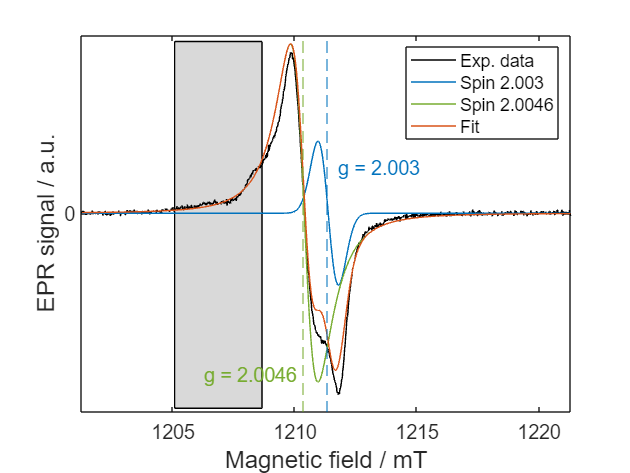

load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
load('data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat');
load("plotColors.mat");
ICW = 5;
x = cw(ICW).x;
y = -real(cw(ICW).y2);

figure()
plot(x, y, 'Color', plotColors(1), 'DisplayName', 'Exp. data')
hold on
plot(x, Fit.fit, 'Color', plotColors(2), 'DisplayName', 'Fit')
plot(x, Fit.yFit0, 'Color',  plotColors(3),  'DisplayName', 'Spin 2.0046')
plot(x, Fit.yFit1, 'Color',  plotColors(4), 'DisplayName', 'Spin 2.003')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.0046), '--', 'Color', plotColors(3), 'HandleVisibility', 'off')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.003), '--', 'Color', plotColors(4), 'HandleVisibility', 'off')
rectangle('position', [x(195) -25 (x(378) - x(195)) 47], 'FaceColor', [.85 .85 .85])

Label = "g = 2.0046";
text(0.25, 0.1, Label, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', plotColors(3));
Label = "g = 2.003";
text(0.525, 0.65, Label, 'Units', 'normalized', ...
'FontSize', 13, 'Color', plotColors(4));

chH = get(gca, "Children");
set(gca,'Children',[chH(6);chH(5);chH(4);chH(7);chH(3);chH(2);chH(1)])

ylim(setAxLim(y, 0.05))
xlim(setAxLim(x, 0))
yticks(0)
legend()
labelAxesFig(gca, "Magnetic field / mT", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00001', '.svg')

## X-band and Q-band plotted on a g-value axis

X-band: gm_09_20230720_dataPreparation,

Q-band: gm_06_20230622_dataPreparation

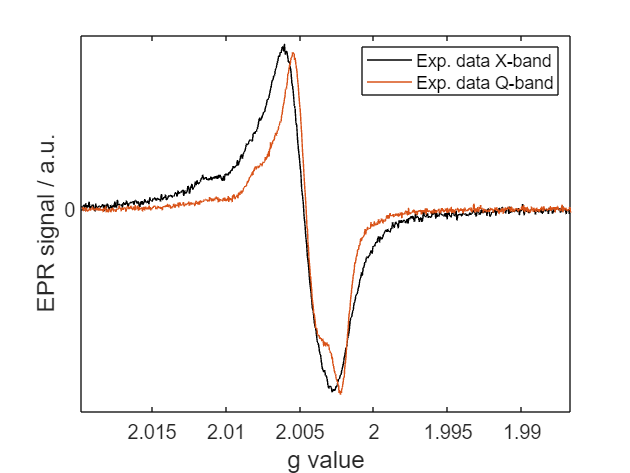

load('data/processed/gm20230720_sample4.mat');
cwX = cw;
load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
cwQ = cw(5);
load("plotColors.mat");

gaxX = planck*cwX.Params.MWFQ/bmagn./(cwX.x/1000);
gaxQ = planck*cwQ.Params.MWFQ/bmagn./(cwQ.x/1000);
% figure()
% tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight')
% nexttile
% plot(cwX.x, cwX.y)
% xlim(setAxLim(cwX.x, 0))
% ylim(setAxLim(cwX.y, 0.05))
% nexttile
% plot(gaxX, cwX.y)
% xlim(setAxLim(gaxX, 0))
% ylim(setAxLim(cwX.y, 0.05))
% set(gca, 'Xdir', 'reverse')
% nexttile
% plot(cwQ.x, cwQ.y)
% xlim(setAxLim(cwQ.x, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% nexttile
% plot(gaxQ, cwQ.y)
% xlim(setAxLim(gaxQ, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% set(gca, 'Xdir', 'reverse')
figure()

plot(gaxX, rescaledata(cwX.y, cwQ.y, 'lsq'), 'Color', plotColors(1), 'DisplayName', 'Exp. data X-band')
hold on
plot(gaxQ, cwQ.y, 'Color', plotColors(2), 'DisplayName', 'Exp. data Q-band')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cwQ.y, 0.05))
xlim(setAxLim(gaxQ, 0))
yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00002', '.svg')

# Comparison between X-band spectra of sample 1b in an X-band tube and sample 4 in an Q-band tube

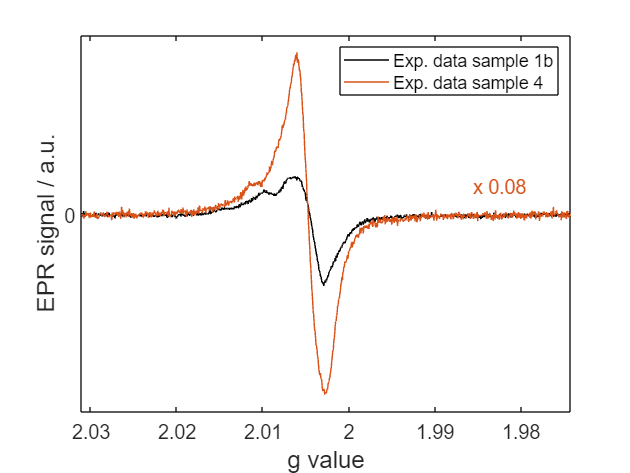

load('data/processed/gm20230720_sample4.mat');
cw4 = cw;
load('data/processed/gm20230804_sample1b.mat');
cw1b = cw;
load("plotColors.mat");

gax4 = planck*cw4.Params.MWFQ/bmagn./(cw4.x/1000);
gax1b = planck*cw1b.Params.MWFQ/bmagn./(cw1b.x/1000);

figure()
plot(gax1b, cw1b.y, 'Color', plotColors(1), 'DisplayName', 'Exp. data sample 1b')
hold on
plot(gax4, cw4.y, 'Color', plotColors(2), 'DisplayName', 'Exp. data sample 4')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cw4.y, 0.05))
xlim(setAxLim(gax4, 0))

% Ratio between Q-band and X-band tube volume. Assume same height (max
% sample space of the SHQ resonator is 1cm, therefore it is a resonable
% assumption):
% (1mm)^2/(3.5mm)^2 = 0.0816.
Label = "x 0.08"; 
text(0.8, 0.6, Label, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', plotColors(2));

yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")
%exportFig(gcf, 'reports/figures', 'sijia-fig-00003', '.svg')

# Degradation of sample from SCOF005 to SCOF008 after 1 day of air exposure

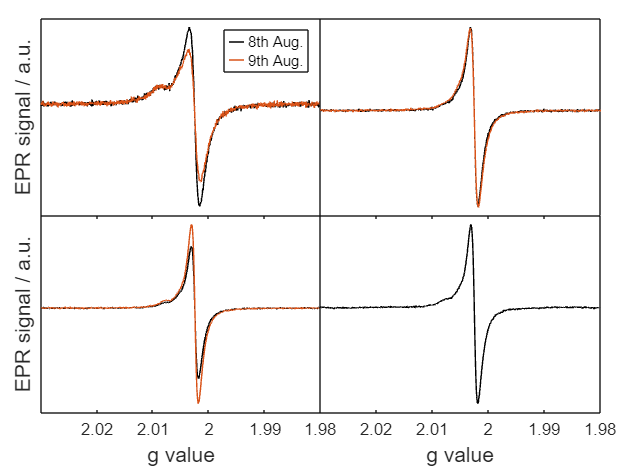

load("plotColors.mat");
figure()
tL = tiledlayout('flow', 'TileSpacing', 'none', 'Padding', 'compact');

data0 = load('data/processed/gm-e1-00034.mat');
data1 = load('data/processed/gm-e1-00038.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])
xticks([])

data0 = load('data/processed/gm-e1-00035.mat');
data1 = load('data/processed/gm-e1-00039.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])
xticks([])

data0 = load('data/processed/gm-e1-00036.mat');
data1 = load('data/processed/gm-e1-00040.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data1.data.y, 0.05))
yticks([])

data0 = load('data/processed/gm-e1-00037.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])

lgd = legendfirsttile(tL, {'8th Aug.', '9th Aug.'});
labelAxesFig(tL, "g value", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00003', '.svg')